# Faza 3

% set(groot, 'DefaultFigureUnits', 'pixels');
set(groot, 'DefaultFigurePosition', [20, 20, 1500, 1000]);
% Instructiune initializare proprietati pentru toate graficele (utila sa
% pot sa maximizez dimensiunile ferestrelor. Asta e folosita pentru
% afisarea graficelor intr-un mod corespunzator in live script, si pentru
% export in PDF. Eventual aceste marimi pot fi modificate.
% Incarcam datele de la fazele anterioare.
load('best_window_step3.mat');
freqz_rez = 5000;

## Punctul a)

Definit printre fisiere este si rutina "check_PPFTI.m", o functie care calculeaza cele 2 tolerante. Vom testa pentru fereastra Kaiser ($\beta+1$).

h_best = fir1(window_length - 1, freq_c, w_kaiser_sup);
[omega_p, omega_s, Delta_p] = PS_PRJ_1_Faza_3b(4, 3);
Delta_s = Delta_p;
[delta_pr, delta_sr] = check_PPFTI(h_best, omega_p, omega_s);
fprintf("delta_pr = %f\ndelta_sr = %f\n", delta_pr, delta_sr);

delta_pr = 0.499998
delta_sr = 0.147668


fprintf("Delta_p = %f\nDelta_s = %f", Delta_p / 100, Delta_s / 100);

Delta_p = 0.052270
Delta_s = 0.052270

## Punctul b)

Avand functia scrisa, vom genera toate filtrele posibile si vom calcula tolerantele si daca aceste abateri respecta valorile propuse de functia apelata pentru faza 3 a proiectului.

omega_c_vec = [(1 - 0.25) * omega_p + 0.25 * omega_s, (1 - 0.5) * omega_p + 0.5 * omega_s, ...
    (1 - 0.75) * omega_p + 0.75 * omega_s];
freq_c_vec = omega_c_vec / pi;
fprintf("Filtre de ordin M\n");

Filtre de ordin M


for i = 1 : 3
    h_M(i, :) = fir1(window_length - 1, freq_c_vec(i), w_kaiser_sup);
    [H_M(i, :), om_M] = freqz(h_M(i, :), 1, freqz_rez);
    [delta_P, delta_S] = check_PPFTI(h_M(i, :), omega_p, omega_s);
    fprintf("delta_p= %f delta_s= %f\n", delta_P, delta_S);
    fprintf("Ordin= %d, Suma tolerante= %f\n", window_length, delta_P + delta_S);
end

delta_p= 0.398632 delta_s= 0.218265


Ordin= 34, Suma tolerante= 0.616897


delta_p= 0.303079 delta_s= 0.303044


Ordin= 34, Suma tolerante= 0.606123


delta_p= 0.218286 delta_s= 0.398599


Ordin= 34, Suma tolerante= 0.616885


fprintf("Filtre de ordin 3/2 * M\n");

Filtre de ordin 3/2 * M


for i = 1 : 3
    h_3div2M(i, :) = fir1(window_length + window_length / 2 - 1, freq_c_vec(i), w_kaiser_3div2);
    [H_3div2M(i, :), om_3div2M] = freqz(h_3div2M(i, :), 1, freqz_rez);
    [delta_P, delta_S] = check_PPFTI(h_3div2M(i, :), omega_p, omega_s);
    fprintf("delta_p= %f delta_s= %f\n", delta_P, delta_S);
    fprintf("Ordin= %d, Suma tolerante= %f\n", window_length + window_length / 2, delta_P + delta_S);
end

delta_p= 0.348314 delta_s= 0.115746


Ordin= 51, Suma tolerante= 0.464060


delta_p= 0.215878 delta_s= 0.215922


Ordin= 51, Suma tolerante= 0.431800


delta_p= 0.115730 delta_s= 0.348346


Ordin= 51, Suma tolerante= 0.464075


fprintf("Filtre de ordin 2M\n");

Filtre de ordin 2M


for i = 1 : 3
    h_2M(i, :) = fir1(2 * window_length - 1, freq_c_vec(i), w_kaiser_2);
    [H_2M(i, :), om_2M] = freqz(h_2M(i, :), 1, freqz_rez);
    [delta_P, delta_S] = check_PPFTI(h_2M(i, :), omega_p, omega_s);
    fprintf("delta_p= %f delta_s= %f\n", delta_P, delta_S);
    fprintf("Ordin= %d, Suma tolerante= %f\n", 2 * window_length, delta_P + delta_S);
end

delta_p= 0.300303 delta_s= 0.050306


Ordin= 68, Suma tolerante= 0.350608


delta_p= 0.143886 delta_s= 0.143875


Ordin= 68, Suma tolerante= 0.287761


delta_p= 0.050335 delta_s= 0.300314


Ordin= 68, Suma tolerante= 0.350649


Dupa analiza rezultatelor, observam ca unele filtre nu respecta toleranta impusa pentru banda de stopare. De exemplu, filtre proaste sunt:

- toate ferestrele de ordin M;

- ferestrele de ordin $M + M \div 2$ cu exceptia celei cu prima frecventa de taiere;

- fereastra de ordin $2 \times M$ cu ultima frecventa de taiere.

Se observa ca marimea ferestrei este invers proportionala cu suma tolerantelor, asa ca criteriile de ordonare a ferestrelor au prioritate in functie de ce rezultat vrem sa scoatem:

- M mai mic $\Rightarrow$ putere de calcul mai mic;

- suma tolerantelor mai mica $\Rightarrow$ filtrare mult mai riguroasa.

In scopul acestui proiect, presupunem ca e mai important ca rezultatul sa fie cat mai apropiat de cel mai bun, asa ca tolerantele conteaza sa fie mai mici.

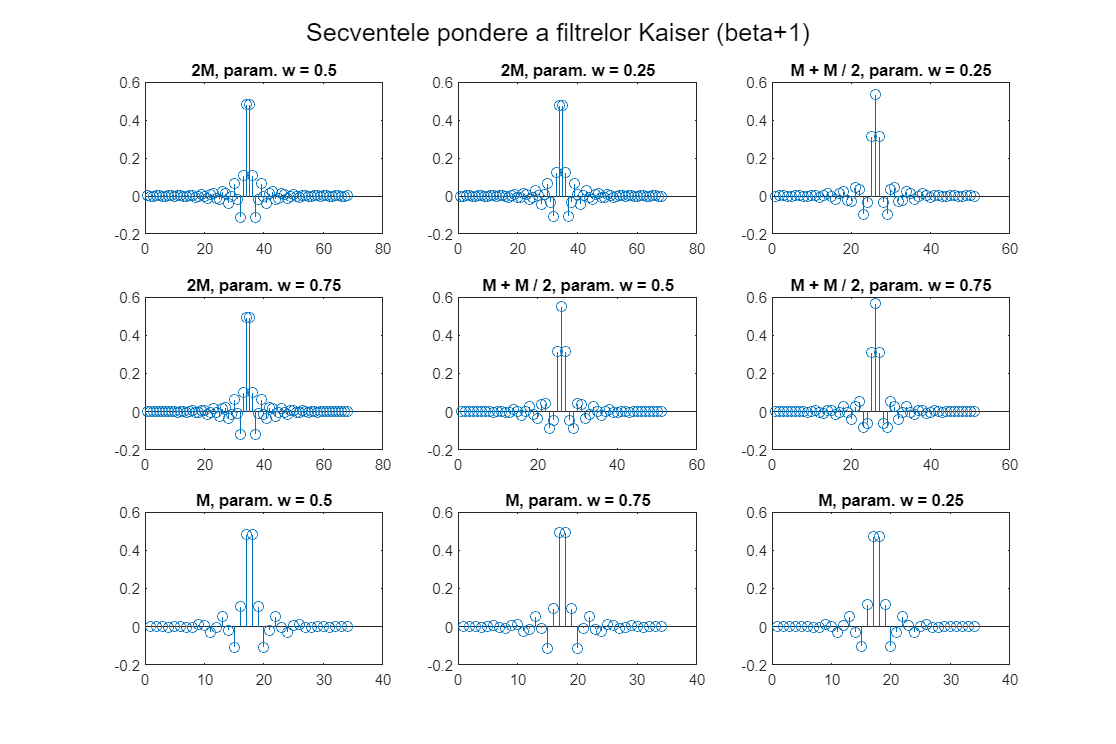

% Mi-am dat seama mai tarziu ca punctele in care freqz isi genereaza
% punctele pe abscisa sunt aceleasi indiferent de rezolutia ferestrei, asa
% ca argumentele generate in plus nu sunt necesare, toate avand aceeasi
% valoare. Acestea o sa fie excluse in script in a mai fi folosite.
fig15 = figure('Name', 'Secventele pondere a filtrelor Kaiser (beta+1)');
subplot(3, 3, 1);
stem(h_2M(2, :));
title("2M, param. w = 0.5");
subplot(3, 3, 2);
stem(h_2M(1, :));
title("2M, param. w = 0.25");
subplot(3, 3, 3);
stem(h_3div2M(1, :));
title("M + M / 2, param. w = 0.25");
subplot(3, 3, 4);
stem(h_2M(3, :));
title("2M, param. w = 0.75");
subplot(3, 3, 5);
stem(h_3div2M(2, :));
title("M + M / 2, param. w = 0.5");
subplot(3, 3, 6);
stem(h_3div2M(3, :));
title("M + M / 2, param. w = 0.75");
subplot(3, 3, 7);
stem(h_M(2, :));
title("M, param. w = 0.5");
subplot(3, 3, 8);
stem(h_M(3, :));
title("M, param. w = 0.75");
subplot(3, 3, 9);
stem(h_M(1, :));
title("M, param. w = 0.25");
sgtitle('Secventele pondere a filtrelor Kaiser (beta+1)');

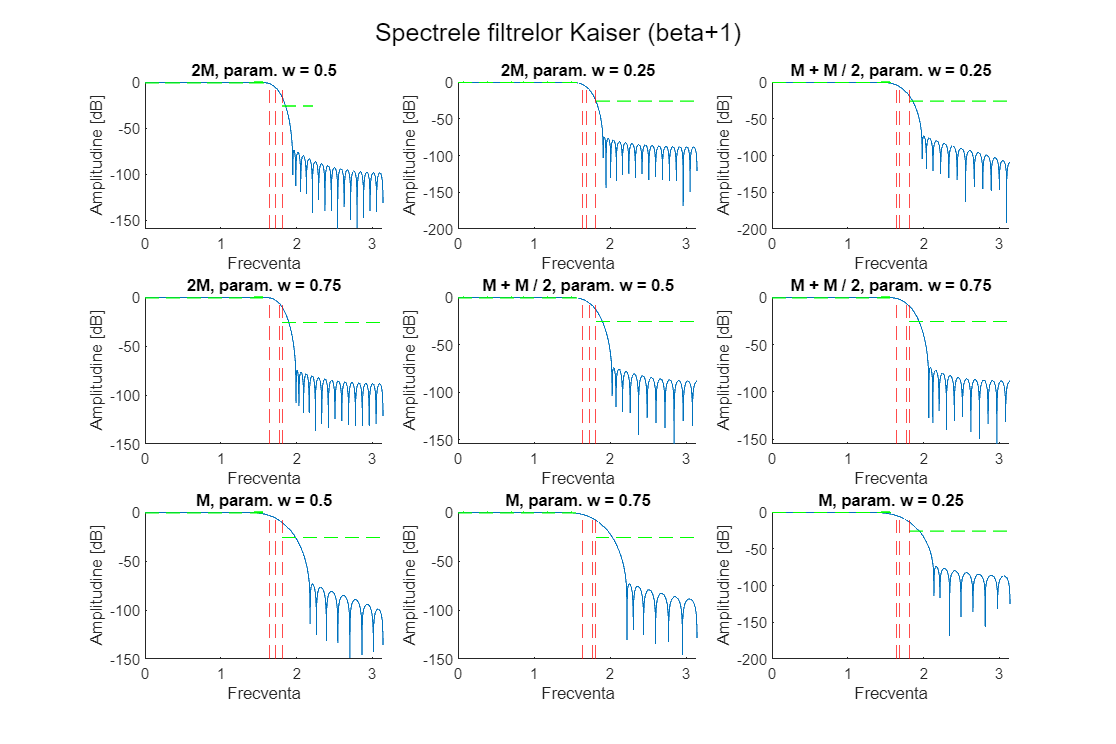

frec_p_M = om_M(om_M <= omega_p);
frec_s_M = om_M(om_M >= omega_s);
len_p_M = length(frec_p_M);
len_s_M = length(frec_s_M);
fig16 = figure('Name', 'Spectrele filtrelor pentru Kaiser (beta+1)');
subplot(3, 3, 1, 'NextPlot', 'add');
plot(om_2M, mag2db(abs(H_2M(2, :))));
hold on
xline(omega_p, 'r--');
xline(omega_s, 'r--');
xline(omega_c_vec(2), 'r--');
plot(frec_p_M, ones(1, len_p_M) * mag2db(1 - Delta_p / 100), 'g--');
plot(frec_p_M, ones(1, len_p_M) * mag2db(1 + Delta_p / 100), 'g--');
plot(frec_s_M, ones(1, len_s_M) * mag2db(Delta_s / 100), 'g--');
hold off
xlabel('Frecventa');
ylabel('Amplitudine [dB]');
title("2M, param. w = 0.5");
subplot(3, 3, 2, 'NextPlot', 'add');
plot(om_2M, mag2db(abs(H_2M(1, :))));
hold on
xline(omega_p, 'r--');
xline(omega_s, 'r--');
xline(omega_c_vec(1), 'r--');
plot(frec_p_M, ones(1, len_p_M) * mag2db(1 - Delta_p / 100), 'g--');
plot(frec_p_M, ones(1, len_p_M) * mag2db(1 + Delta_p / 100), 'g--');
plot(frec_s_M, ones(1, len_s_M) * mag2db(Delta_s / 100), 'g--');
hold off
xlabel('Frecventa');
ylabel('Amplitudine [dB]');
title("2M, param. w = 0.25");
subplot(3, 3, 3, 'NextPlot', 'add');
plot(om_3div2M, mag2db(abs(H_3div2M(1, :))));
hold on
xline(omega_p, 'r--');
xline(omega_s, 'r--');
xline(omega_c_vec(1), 'r--');
plot(frec_p_M, ones(1, len_p_M) * mag2db(1 - Delta_p / 100), 'g--');
plot(frec_p_M, ones(1, len_p_M) * mag2db(1 + Delta_p / 100), 'g--');
plot(frec_s_M, ones(1, len_s_M) * mag2db(Delta_s / 100), 'g--');
hold off
xlabel('Frecventa');
ylabel('Amplitudine [dB]');
title("M + M / 2, param. w = 0.25");
subplot(3, 3, 4, 'NextPlot', 'add');
plot(om_2M, mag2db(abs(H_2M(3, :))));
hold on
xline(omega_p, 'r--');
xline(omega_s, 'r--');
xline(omega_c_vec(3), 'r--');
plot(frec_p_M, ones(1, len_p_M) * mag2db(1 - Delta_p / 100), 'g--');
plot(frec_p_M, ones(1, len_p_M) * mag2db(1 + Delta_p / 100), 'g--');
plot(frec_s_M, ones(1, len_s_M) * mag2db(Delta_s / 100), 'g--');
hold off
xlabel('Frecventa');
ylabel('Amplitudine [dB]');
title("2M, param. w = 0.75");
subplot(3, 3, 5, 'NextPlot', 'add');
plot(om_3div2M, mag2db(abs(H_3div2M(2, :))));
hold on
xline(omega_p, 'r--');
xline(omega_s, 'r--');
xline(omega_c_vec(2), 'r--');
plot(frec_p_M, ones(1, len_p_M) * mag2db(1 - Delta_p / 100), 'g--');
plot(frec_p_M, ones(1, len_p_M) * mag2db(1 + Delta_p / 100), 'g--');
plot(frec_s_M, ones(1, len_s_M) * mag2db(Delta_s / 100), 'g--');
hold off
xlabel('Frecventa');
ylabel('Amplitudine [dB]');
title("M + M / 2, param. w = 0.5");
subplot(3, 3, 6, 'NextPlot', 'add');
plot(om_3div2M, mag2db(abs(H_3div2M(3, :))));
hold on
xline(omega_p, 'r--');
xline(omega_s, 'r--');
xline(omega_c_vec(3), 'r--');
plot(frec_p_M, ones(1, len_p_M) * mag2db(1 - Delta_p / 100), 'g--');
plot(frec_p_M, ones(1, len_p_M) * mag2db(1 + Delta_p / 100), 'g--');
plot(frec_s_M, ones(1, len_s_M) * mag2db(Delta_s / 100), 'g--');
hold off
xlabel('Frecventa');
ylabel('Amplitudine [dB]');
title("M + M / 2, param. w = 0.75");
subplot(3, 3, 7, 'NextPlot', 'add');
plot(om_M, mag2db(abs(H_M(2, :))));
hold on
xline(omega_p, 'r--');
xline(omega_s, 'r--');
xline(omega_c_vec(2), 'r--');
plot(frec_p_M, ones(1, len_p_M) * mag2db(1 - Delta_p / 100), 'g--');
plot(frec_p_M, ones(1, len_p_M) * mag2db(1 + Delta_p / 100), 'g--');
plot(frec_s_M, ones(1, len_s_M) * mag2db(Delta_s / 100), 'g--');
hold off
xlabel('Frecventa');
ylabel('Amplitudine [dB]');
title("M, param. w = 0.5");
subplot(3, 3, 8, 'NextPlot', 'add');
plot(om_M, mag2db(abs(H_M(3, :))));
hold on
xline(omega_p, 'r--');
xline(omega_s, 'r--');
xline(omega_c_vec(3), 'r--');
plot(frec_p_M, ones(1, len_p_M) * mag2db(1 - Delta_p / 100), 'g--');
plot(frec_p_M, ones(1, len_p_M) * mag2db(1 + Delta_p / 100), 'g--');
plot(frec_s_M, ones(1, len_s_M) * mag2db(Delta_s / 100), 'g--');
hold off
xlabel('Frecventa');
ylabel('Amplitudine [dB]');
title("M, param. w = 0.75");
subplot(3, 3, 9, 'NextPlot', 'add');
plot(om_M, mag2db(abs(H_M(1, :))));
hold on
xline(omega_p, 'r--');
xline(omega_s, 'r--');
xline(omega_c_vec(1), 'r--');
plot(frec_p_M, ones(1, len_p_M) * mag2db(1 - Delta_p / 100), 'g--');
plot(frec_p_M, ones(1, len_p_M) * mag2db(1 + Delta_p / 100), 'g--');
plot(frec_s_M, ones(1, len_s_M) * mag2db(Delta_s / 100), 'g--');
hold off
xlabel('Frecventa');
ylabel('Amplitudine [dB]');
title("M, param. w = 0.25");
sgtitle('Spectrele filtrelor Kaiser (beta+1)');

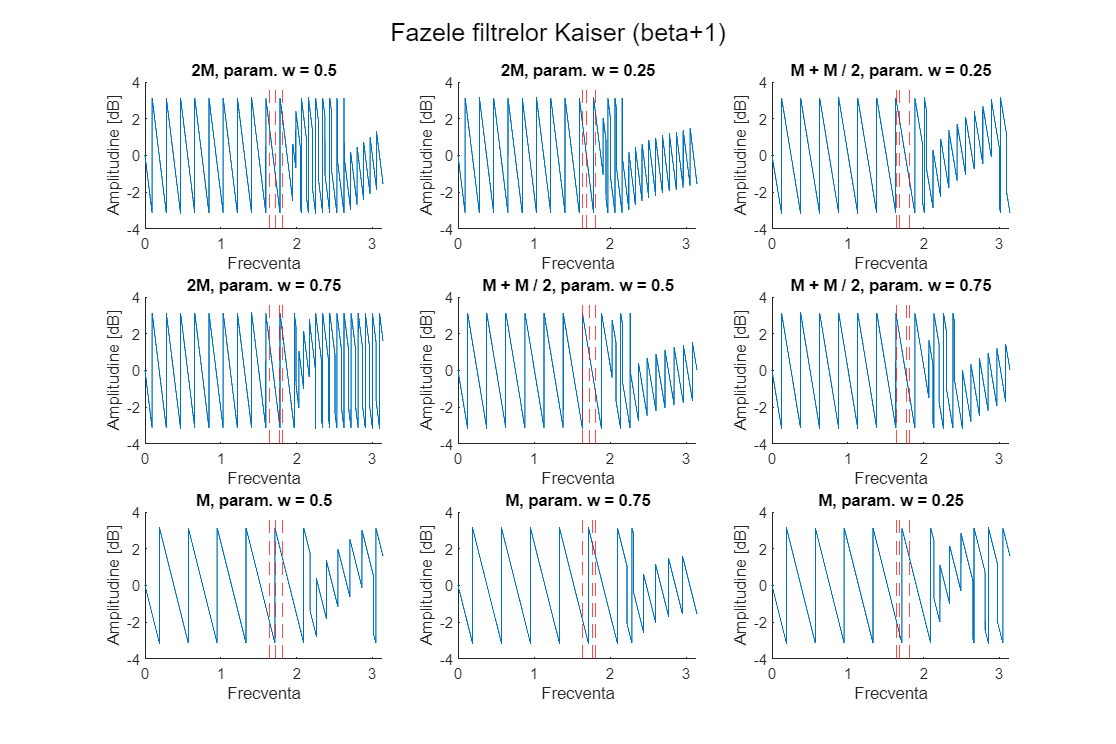

fig16 = figure('Name', 'Fazele filtrelor pentru Kaiser (beta+1)');
subplot(3, 3, 1, 'NextPlot', 'add');
plot(om_2M, angle(H_2M(2, :)));
hold on
xline(omega_p, 'r--');
xline(omega_s, 'r--');
xline(omega_c_vec(2), 'r--');
hold off
xlabel('Frecventa');
ylabel('Amplitudine [dB]');
title("2M, param. w = 0.5");
subplot(3, 3, 2, 'NextPlot', 'add');
plot(om_2M, angle(H_2M(1, :)));
hold on
xline(omega_p, 'r--');
xline(omega_s, 'r--');
xline(omega_c_vec(1), 'r--');
hold off
xlabel('Frecventa');
ylabel('Amplitudine [dB]');
title("2M, param. w = 0.25");
subplot(3, 3, 3, 'NextPlot', 'add');
plot(om_3div2M, angle(H_3div2M(1, :)));
hold on
xline(omega_p, 'r--');
xline(omega_s, 'r--');
xline(omega_c_vec(1), 'r--');
hold off
xlabel('Frecventa');
ylabel('Amplitudine [dB]');
title("M + M / 2, param. w = 0.25");
subplot(3, 3, 4, 'NextPlot', 'add');
plot(om_2M, angle(H_2M(3, :)));
hold on
xline(omega_p, 'r--');
xline(omega_s, 'r--');
xline(omega_c_vec(3), 'r--');
hold off
xlabel('Frecventa');
ylabel('Amplitudine [dB]');
title("2M, param. w = 0.75");
subplot(3, 3, 5, 'NextPlot', 'add');
plot(om_3div2M, angle(H_3div2M(2, :)));
hold on
xline(omega_p, 'r--');
xline(omega_s, 'r--');
xline(omega_c_vec(2), 'r--');
hold off
xlabel('Frecventa');
ylabel('Amplitudine [dB]');
title("M + M / 2, param. w = 0.5");
subplot(3, 3, 6, 'NextPlot', 'add');
plot(om_3div2M, angle(H_3div2M(3, :)));
hold on
xline(omega_p, 'r--');
xline(omega_s, 'r--');
xline(omega_c_vec(3), 'r--');
hold off
xlabel('Frecventa');
ylabel('Amplitudine [dB]');
title("M + M / 2, param. w = 0.75");
subplot(3, 3, 7, 'NextPlot', 'add');
plot(om_M, angle(H_M(2, :)));
hold on
xline(omega_p, 'r--');
xline(omega_s, 'r--');
xline(omega_c_vec(2), 'r--');
hold off
xlabel('Frecventa');
ylabel('Amplitudine [dB]');
title("M, param. w = 0.5");
subplot(3, 3, 8, 'NextPlot', 'add');
plot(om_M, angle(H_M(3, :)));
hold on
xline(omega_p, 'r--');
xline(omega_s, 'r--');
xline(omega_c_vec(3), 'r--');
hold off
xlabel('Frecventa');
ylabel('Amplitudine [dB]');
title("M, param. w = 0.75");
subplot(3, 3, 9, 'NextPlot', 'add');
plot(om_M, angle(H_M(1, :)));
hold on
xline(omega_p, 'r--');
xline(omega_s, 'r--');
xline(omega_c_vec(1), 'r--');
hold off
xlabel('Frecventa');
ylabel('Amplitudine [dB]');
title("M, param. w = 0.25");
sgtitle('Fazele filtrelor Kaiser (beta+1)');

save('criterii_faza4.mat', 'omega_p', 'omega_s', 'Delta_p', 'Delta_s');

Concluzie: din graficul unde sunt prezentate spectrele tuturor filtrelor, acolo unde am variat lungimea ferestrei si unghiul de taiere, se poate verifica vizual calculul numeric facut mai devreme. Interesant de precizat ca cele mai bune rezultate din punct de vedere a tolerantelor se regasesc pentru frecventa de taiere in mijlocul zonei tranzitorii.